%% 1. Clear and Close Figures
% clear ; close all; clc

## %% ========= Part 1: Data (PREDICT)================

fprintf('\n \nDATA\n.... \n \n \n');   


 
DATA
.... 
 
 



%% 2. Data
fprintf('Loading data ...\n'); 

Loading data ...


    %%%%%%********Drug-disease********  
    
    load('DiDrAMat.mat'); 
    fprintf('\n\nPlot  Sparsity\n\n');  



Plot  Sparsity



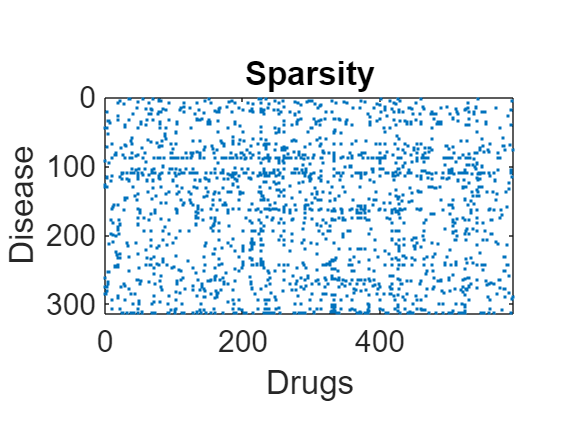

    spy(DiDrAMat)
    title('Sparsity')
    ylabel('Disease');
    xlabel('Drugs');

    %%%%%%********Dis-dis********  
    DiseaseSimMat=importdata('DR.mat');
    fprintf('\n\nPlot  DiseaseSimMat\n\n');   



Plot  DiseaseSimMat



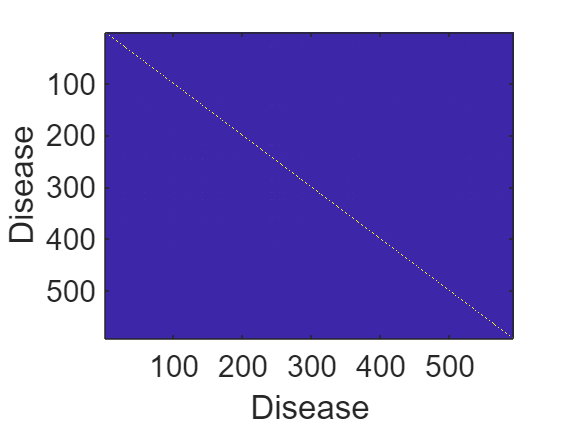

    imagesc(DiseaseSimMat);
    ylabel('Disease');
    xlabel('Disease');

    
    %%%%%%********drug-drug********  
    DrugSimMat=importdata('DIS.mat');
    fprintf('\n\nPlot  DrugSimMat\n\n');   



Plot  DrugSimMat



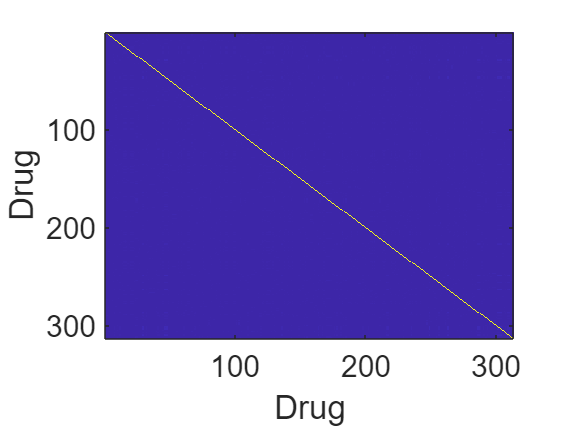

    imagesc(DrugSimMat);
    ylabel('Drug');
    xlabel('Drug');

%     diseaseList = loadDisList();
%     drList = importdata('DrugsName.txt');
%     W1=[DrugSimMat DiDrAMat';DiDrAMat DiseaseSimMat];
%     imagesc(W1);
%     ylabel('x');
%     xlabel('y');
%     Wrname = importdata('DrugsName');
%     Wdname = importdata('DiseasesName');


## %% ======= Part 2: Normaization and Analysis==========

% d = log(9999);
% newWrr = importdata('shareWrr.mat');
% newWdd = importdata('shareWdd.mat');
%       
% LWrr = DrugSimMat;
% LWdd = DiseaseSimMat;
% cr = setparFun(DiDrAMat',LWrr);
% cd = setparFun(DiDrAMat,LWdd);
% cr 
% cd
% LWrr = 1./(1+exp(cr*LWrr+d));
% LWdd = 1./(1+exp(cd*LWdd+d));
% [RWrr,RWdd] = nManiCluester(LWrr,LWdd,newWrr,newWdd,Wrname,Wdname);
% normWrr = normFun(RWrr);
% normWdd = normFun(RWdd);
%X=DrugSimMat* DiDrAMatcase{5}* DiseaseSimMat;
X=DrugSimMat* DiDrAMat* DiseaseSimMat;
 X=DiDrAMat.*X;
%     imagesc(X);
%     ylabel('x');
%     xlabel('y');
% c=0;
%     for i=1:size(DiDrAMatcase5,1)
%         for j=1:size(DiDrAMatcase5,2)
%             if DiDrAMatcase5(i,j)==1
%                 c=c+1;              
%             end
%         end
%     end
%     c
%

**%%=====initializations**

r =50;
[m,n] = size(X); 
maxiter = 1e6; timelimit = 10;
% Compare three SVD-based NMF initializations and random initialization 
% 1) NNDSVD
fprintf('Running NNDSVD...'), 

Running NNDSVD...

tic; 
[W1,H1] = NNDSVD(X,r,1);
fprintf(' Done. Computational time = %2.2f s.\n', toc); 

 Done. Computational time = 0.05 s.


% 2) SVD-NMF
fprintf('Running SVD-NMF...'), 

Running SVD-NMF...

tic; 
[W2,H2] = SVDNMF(X,r); 
fprintf(' Done. Computational time = %2.2f s.\n', toc); 

 Done. Computational time = 0.03 s.


% 3) NNSVDLRC
fprintf('Running NNSVD-LRC...'), 

Running NNSVD-LRC...

tic; 
[W3,H3] = NNSVDLRC(X,r); 
fprintf(' Done. Computational time = %2.2f s.\n', toc); 

 Done. Computational time = 0.03 s.


% 4) Random initialization
W4 = rand(m,r); 
H4 = rand(r,n); 


% Display evolution of A-HALS error for the 3 initializations 
[W1n,H1n,e1n] = HALSacc(X,W1,H1,0,0,maxiter,timelimit); 
[W2n,H2n,e2n] = HALSacc(X,W2,H2,0,0,maxiter,timelimit); 
[W3n,H3n,e3n] = HALSacc(X,W3,H3,0,0,maxiter,timelimit); 
[W4n,H4n,e4n] = HALSacc(X,W4,H4,0,0,maxiter,timelimit); 

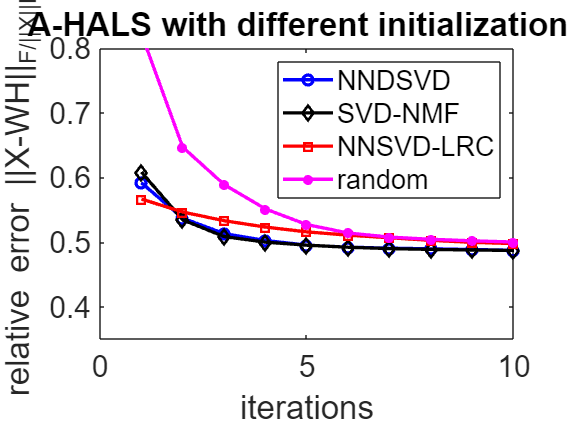


figure; 
set(0, 'DefaultAxesFontSize', 18);
set(0, 'DefaultLineLineWidth', 2);

nX = norm(X,'fro'); %Frobenius norm of a sparse matrix
plot(e1n/nX,'bo-'); hold on; 
plot(e2n/nX,'kd-');
plot(e3n/nX,'rs-'); 
plot(e4n/nX,'m*-'); 
legend('NNDSVD', 'SVD-NMF', 'NNSVD-LRC', 'random'); 
ylabel('relative error ||X-WH||_F/||X||_F'); 
xlabel('iterations'); 
title('A-HALS with different initializations'); 
axis([0 10 0.35 0.8]); 

Y1=W1n*H1n;

A1 = reshape(DiDrAMat',[],1);
B1 = reshape(Y1',[],1);
[M1,L1,T1,AUC1] = perfcurve(A1,B1,1);
AUC1

AUC1 = 0.9841

figure
title('ROC')
plot(M1,L1)
hold on
ylabel('TPR');
xlabel('FPR');

%%-------------------
Y2=W2n*H2n;

A2 = reshape(DiDrAMat',[],1);
B2 = reshape(Y2',[],1);
[M2,L2,T2,AUC2] = perfcurve(A2,B2,1);
AUC2

AUC2 = 0.9842

title('ROC')
plot(M2,L2)
hold on
ylabel('TPR');
xlabel('FPR');
% %%---------------------
Y3=W3n*H3n;

A3 = reshape(DiDrAMat',[],1);
B3 = reshape(Y3',[],1);
[M3,L3,T3,AUC3] = perfcurve(A3,B3,1);
AUC3

AUC3 = 0.9835

title('ROC')
plot(M3,L3)
hold on
ylabel('TPR');
xlabel('FPR');
% %%-----------------
Y4=W4n*H4n;

A4 = reshape(DiDrAMat',[],1);
B4 = reshape(Y4',[],1);
[M4,L4,T4,AUC4] = perfcurve(A4,B4,1);
AUC4

AUC4 = 0.9835

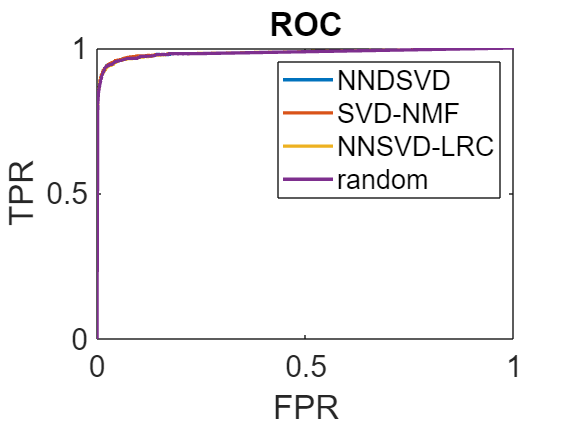

title('ROC')
plot(M4,L4)
hold on
ylabel('TPR');
xlabel('FPR');
legend('NNDSVD', 'SVD-NMF', 'NNSVD-LRC', 'random');


% prec_rec(A1, B1);
% prec_rec(A1, B1, 'holdFigure', 1);
% legend('plotpr','A1/B1','A1/B1','Location','SouthEast');

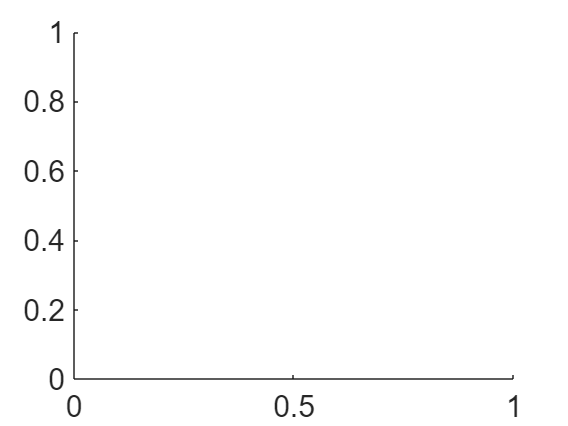

figure
hold on

aupr1=pr_curve(B1,A1,'red')

Unrecognized function or variable 'pr_curve'.

aupr2=pr_curve(B2,A2,'blue')
aupr3=pr_curve(B3,A3,'green')
aupr4=pr_curve(B4,A4,'black')


[ACC,PRE,SEN,F1_score,MCC]=myACC( B3,A3,'accMAX' )


I = ~isnan(X) & ~isnan(Y4); 
data = X(I); estimate = Y4(I);
r=sqrt(sum((X(:)-Y4(:)).^2)/numel(data));